clear all

Gras_Gain = 20; % as string , What gain did you use on the gras mic

freqs = (10:1:100)*1e3; %freqs for which we return the calibration result

pulse_dur = .01; % duration of your pulses- eg. 0.01 equiv to 10 ms

pulse_interval = .05; % duration of the time between pulses

gain_pet = 28; % gain of the microphone you want to calibrate

gain_speaker = 50; % gain of your speaker

findx = 1: 32; %how many recordings you have 
 
freq_start = 10000; %starting frequency
 
freq_step = 1000; % what you want to calibrate, calibrate for each frequency
 
num_freqs = 91; %number of frequencies you want to calibrate for 
 
freq_index = 35; % which frequency you wanto to show the polar plot for

reference_voltage = 3.24 % refernce voltage for you speaker 

reference_voltage = 3.2400

%GRAS_sens = calculateGrasMicrophoneSensitivity_1khz(Gras_Gain);
GRAS_sens = calculateGrasMicrophoneSensitivity_1khz(Gras_Gain);

Calculated GRAS Microphone Sensitivity: -93.7692 dB


 
 % Following the function call
disp(['Calculated GRAS Microphone Sensitivity: ', num2str(GRAS_sens), ' dB']); % This is an alert to signal all is proccessed correctly to this point, being calculated in dbV @ 20 mico piscals

Calculated GRAS Microphone Sensitivity: -93.7692 dB


% Additional code can follow here

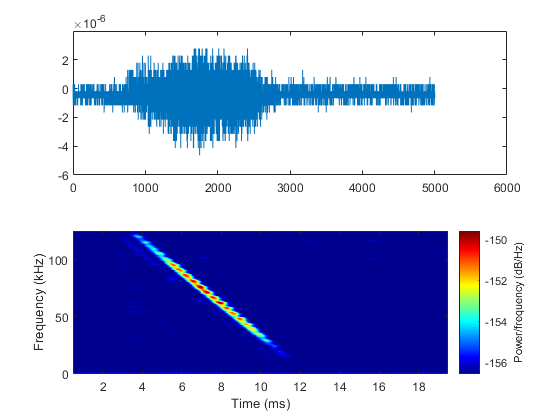

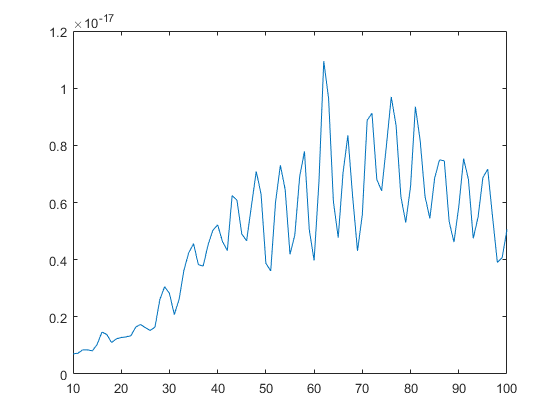

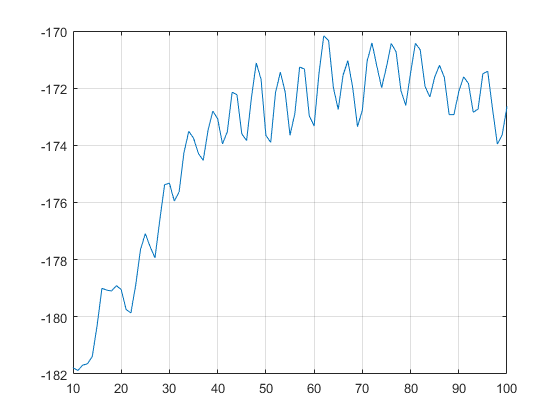

Figure saved as C:\Users\batlab\Downloads\speaker_sens_dB.png



processCalibrationData_gras(freqs, pulse_dur, pulse_interval,gain_speaker);

%extract calibration from speaker and gras mics: creates the following
% Time Domain plot of processed pulse: This plot shows the individual calibration pulses extracted around each peak detected in the squared waveform data. Displaying this plot helps in visually confirming that the pulse extraction is aligned correctly around the detected peaks and that the waveform looks as expected (i.e., no clipping, sufficient data around peaks, etc.).
% A spectrogram
%Power Spectral Density (PSD) Plot of Each Pulse: how the power is distributed across different frequencies. The frequency values are converted from Hz to kHz for easier reading.
%Mean Power Spectral Density Plot: averaged across all pulses

Didn't find 50 pulses in recording


Didn't find 50 pulses in recording


Didn't find 50 pulses in recording


Didn't find 50 pulses in recording


Didn't find 50 pulses in recording


Didn't find 50 pulses in recording


Didn't find 50 pulses in recording


Didn't find 50 pulses in recording


Didn't find 50 pulses in recording


Didn't find 50 pulses in recording


Didn't find 50 pulses in recording


Didn't find 50 pulses in recording


Didn't find 50 pulses in recording


Didn't find 50 pulses in recording


Didn't find 50 pulses in recording


Didn't find 50 pulses in recording


Didn't find 50 pulses in recording


Didn't find 50 pulses in recording


Didn't find 50 pulses in recording


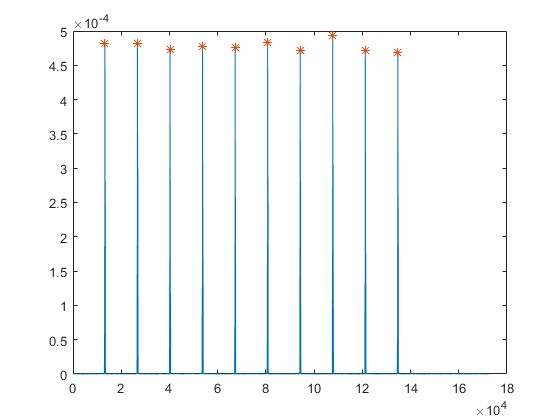

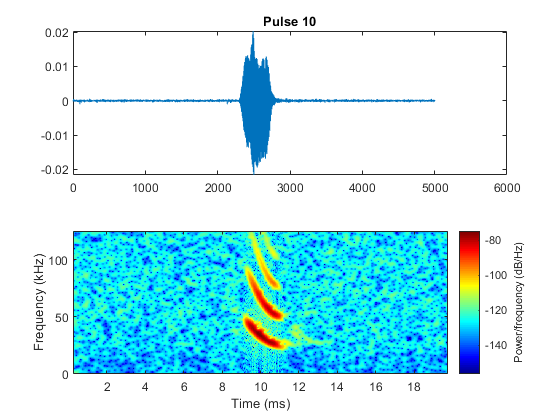

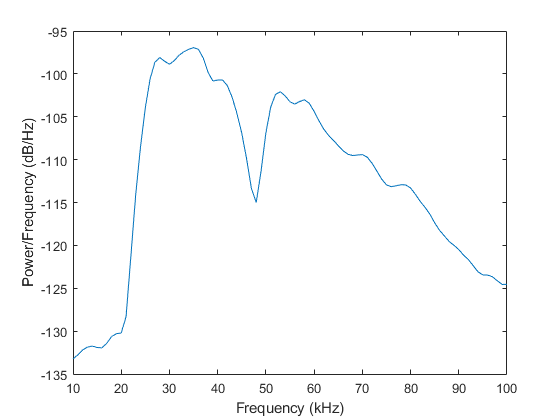

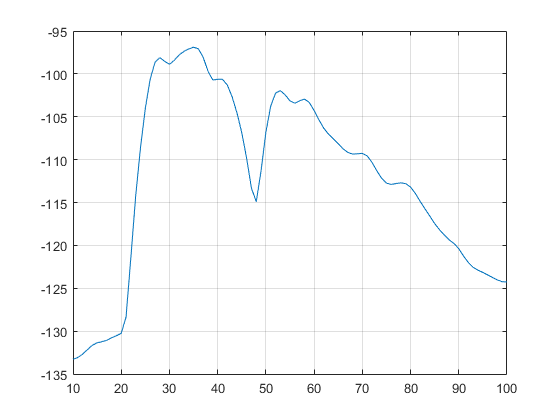

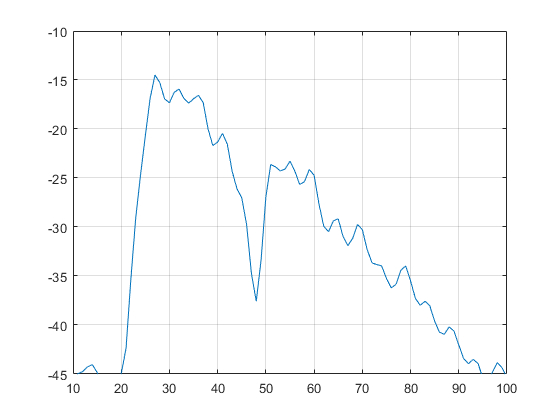

% Copy_of_analyzeMicrophoneSensitivity_regularMic(freqs, pulse_dur, pulse_interval, gain_pet, GRAS_sens, gain_speaker,findx);
analyzeMicrophoneSensitivity_regularMic(freqs, pulse_dur, pulse_interval, gain_pet, GRAS_sens, gain_speaker)

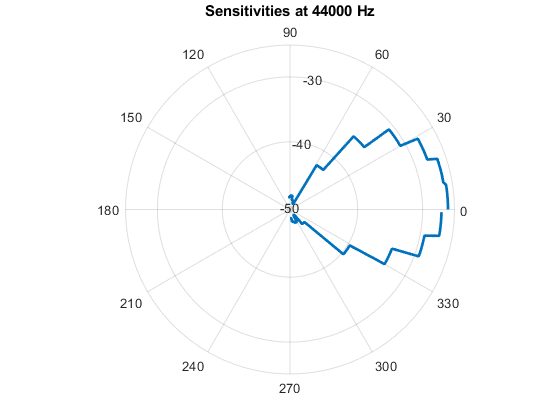

combineAndPlotSensitivities( freq_start,freq_step,num_freqs, freq_index)